clear
close all
clc

% Load OCP data from Excel files
file1 = 'Area Vs OCP pitting.xlsx';
file2 = 'Area vs OCP non Pitting.xlsx';

% Read OCP data from both Excel files
data_pitting = xlsread(file1, 1);  % Assuming data is in the first sheet
data_nonpitting = xlsread(file2, 1);  % Assuming data is in the first sheet

% Separate distance and OCP values for deformed and non-deformed datasets
Area_Pitting = data_pitting(:, 1);
OCP_Pitting = data_pitting(:, 2);

Area_nonPitting = data_nonpitting(:, 1);
OCP_nonPitting = data_nonpitting(:, 2);

% Tabulate data
Area = [Area_nonPitting; Area_Pitting];
Pitting = [[repmat("No Pitting", 158,1)]; [repmat("Pitting", 39,1)] ];
OCP = [OCP_nonPitting; OCP_Pitting];
data = table( Area, Pitting, OCP);

% Fit a linear model to determine if OCP is different between landings
% where pits occured and if this is affected by area.
fit_pit = fitlm(data, 'interactions', 'RobustOpts','on')

fit_pit = Linear regression model (robust fit):
    OCP ~ 1 + Area*Pitting

Estimated Coefficients:
                             Estimate         SE          tStat        pValue  
                            ___________    _________    _________    __________

    (Intercept)                -0.32817    0.0080219       -40.91    4.8061e-97
    Area                      0.0071451    0.0023363       3.0583      0.002542
    Pitting_Pitting         -0.00087012      0.02316    -0.037571       0.97007
    Area:Pitting_Pitting      0.0059839      0.01027      0.58265       0.56081


Number of observations: 197, Error degrees of freedom: 193
Root Mean Squared Error: 0.0414
R-squared: 0.0708,  Adjusted R-Squared: 0.0564
F-statistic vs. constant model: 4.9, p-value = 0.00264

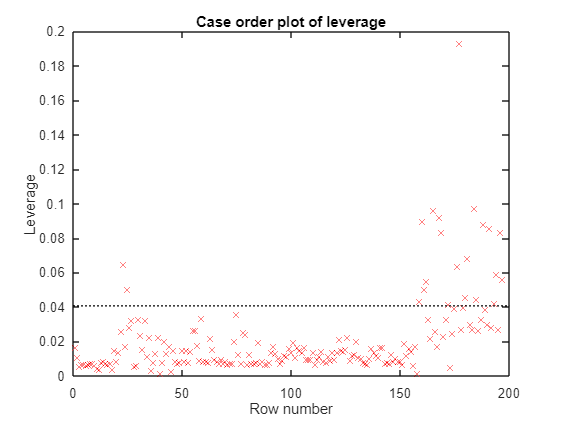

plotDiagnostics(fit_pit)

anova(fit_pit)

ans = 4×5 table
                      SumSq       DF       MeanSq         F        pValue  
                    __________    ___    __________    _______    _________

    Area              0.018409      1      0.018409     10.737    0.0012451
    Pitting          0.0039615      1     0.0039615     2.3106      0.13013
    Area:Pitting    0.00058204      1    0.00058204    0.33948      0.56081
    Error               0.3309    193     0.0017145                        


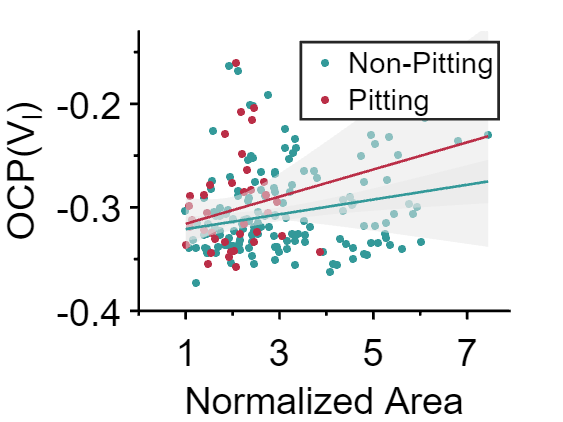

% Plot the raw data (Area vs Pitting, scatter)
figure;
hold on;
scatter(Area_nonPitting, OCP_nonPitting, 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.2, 0.6, 0.6]); % blue for non-deformed
scatter(Area_Pitting, OCP_Pitting, 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.73, 0.18, 0.28]); % pink for deformed


% Set the axis limits and ticks based on the data range
xlim([0 7.9])  % Adjust x-axis limits
xticks(1:2:8)

ylim([-0.4 -0.13])
%yticks(-0.8:0.1:-0.1)

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 0:2:8; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = -0.85:0.05:-0.1; % Minor ticks which don't line up with majors 

% Format the plot appearance
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal');

% Label axes
xlabel('Normalized Area', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')
ylabel('OCP(V_A_g_/_A_g_C_l)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')

newcolors={'[0.73, 0.18, 0.28]', '[0.2, 0.6, 0.6]'};

colororder(newcolors)
%axis equal;  % Makes the x-axis and y-axis have the same length

hold on


% Generate points for plotting the regression curves
Area = transpose( linspace(min(Area), max(Area), 100) ); % Range of Area
Pitting = repmat("Pitting", 100, 1);
pred_Pit = table(Area, Pitting);

Pitting = repmat("No Pitting", 100, 1);
pred_NoPit = table(Area, Pitting);

[y_fit_pit, y_ci_pit] = predict(fit_pit, pred_Pit); % Predicted values with 95% confidence intervals
[y_fit_no, y_ci_no] = predict(fit_pit, pred_NoPit); % Predicted values with 95% confidence intervals

% Fill the confidence region (shaded area) FIRST
fill([Area; flipud(Area)], [y_ci_pit(:,2); flipud(y_ci_pit(:,1))], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
fill([Area; flipud(Area)], [y_ci_no(:,2); flipud(y_ci_no(:,1))], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Plot the regression lines SECOND
prob_line = plot(Area, y_fit_pit, 'LineWidth', 2, 'Color', '[0.73, 0.18, 0.28]'); % Red dashed line for the probability curve
prob_line = plot(Area, y_fit_no, 'LineWidth', 2, 'Color', '[0.2, 0.6, 0.6]'); % Red dashed line for the probability curve

% Add a legend for the probability line
%legend(prob_line, 'Poisson Regression', 'FontSize', 20, 'Location', 'northeast');

legend('Non-Pitting','Pitting', '', '', '', '', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 22);

hold off;